## LAPLACE DISTRIBUTION


$$\mu = 2$$



$$b =2$$


mu = 2;
b = 2;
interval_begin = -50;
interval_end = 50;
number_of_partitions = 100000;

Laplace Probability Density Function = $\frac{1}{2b}exp\left(-\frac{|x-\mu|}{b}\right)$

x = linspace(interval_begin, interval_end, number_of_partitions);
pdf = exp(-(abs(x-mu)./b))./(2*b); % laplace pdf

Now to calculate Cumulative Distribution Function,

cdf = zeros(1, number_of_partitions); % for storing laplace cdf
for i = 2 : 1 : number_of_partitions % calculating laplace cdf
    cdf(1, i) = cdf(1, i-1) + ((interval_end-interval_begin)/number_of_partitions)*pdf(1, i-1);
end

Now plotting CDF and PDF,

hold on;

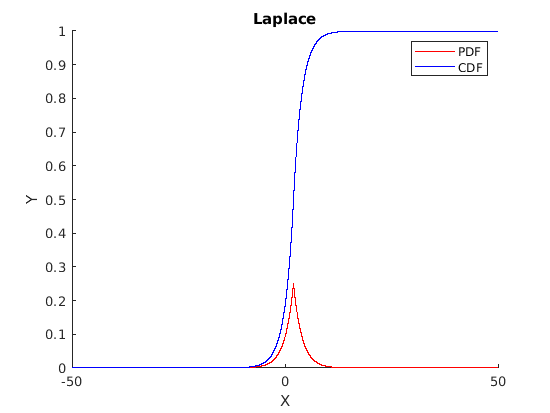

plot(x, pdf, 'r');
plot(x, cdf, 'b');
legend(["PDF","CDF"]);
title("Laplace");
xlabel("X");
ylabel("Y");
hold off;

To calculate variance by Reimann approximation,

Calculating the expectation value,


$$$$E[X]=\int_{-\infty}^{+\infty}xP(x)dx$$$$


expectation = 0;
for i = 2:1:number_of_partitions
    expectation = expectation + ((interval_end-interval_begin)/number_of_partitions).*pdf(1,i).*x(1,i);
end

Calculating the variance,


$$$$Var(X)=E[(X-E[X])^{2}]$$$$



$$$$Var(X)=\int_{-\infty}^{+\infty}(x-E[X])^{2}P(x)dx$$$$


variance = 0;
for i= 2:1:number_of_partitions
    variance= variance+ ((interval_end-interval_begin)/number_of_partitions).*pdf(1,i).*(x(1,i)-expectation).*(x(1,i)-expectation);
end

disp("By reimann approx. Variance = " + variance);

By reimann approx. Variance = 7.9999


Variance by analytical method  = $2b^{2}$

disp("Analytically variance = " + 2*b*b);

Analytically variance = 8
